clc; clear; close all
cd 'G:\Jiaxu Song\Ag_in_warter\Sigma Ag in Water images'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'

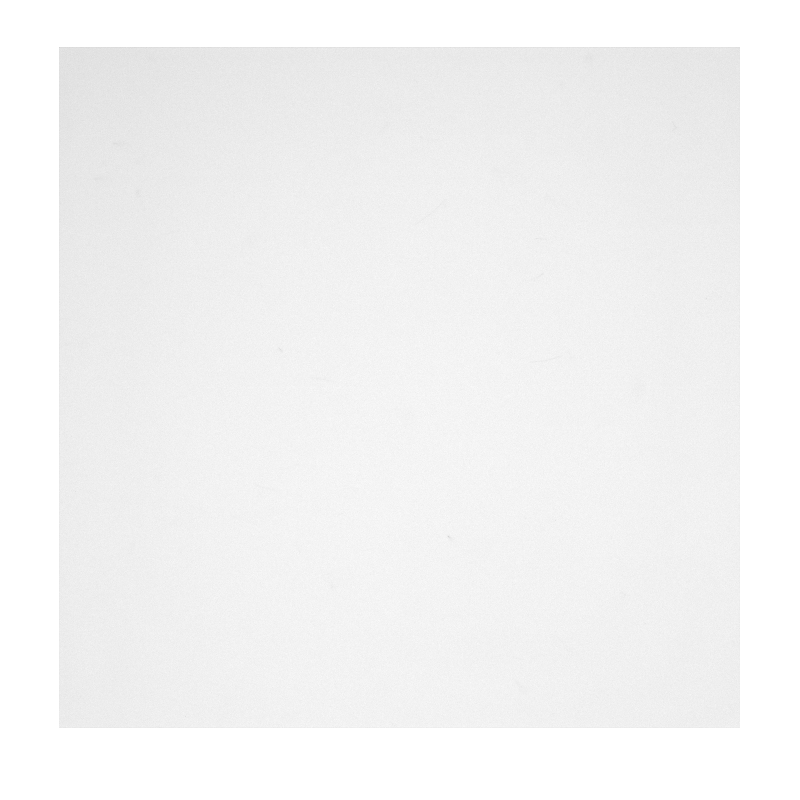

I = imread("40um x 50nm Ag in Water, before sonication.tif");
imshow(I)

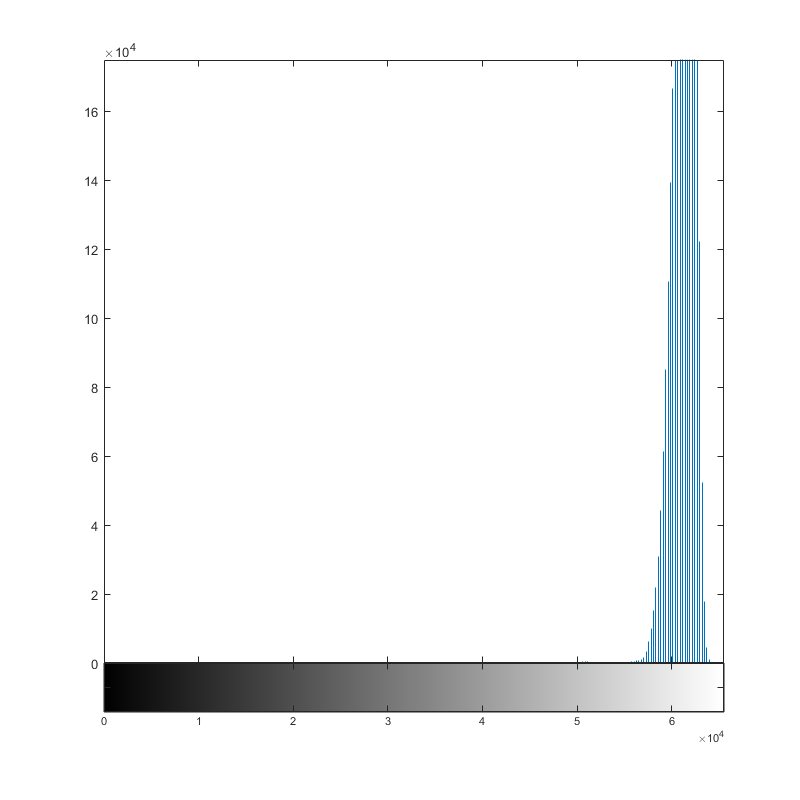

imhist(I)

a = 0; b = 65535;
c = 50; d = 50000; g = 1; A = 1;
P_out = double((I-c) * ((b-a)/(d-c)) + a);
P_out_gamma = A.*P_out.^g;
imshow(P_out)

imshow(P_out_gamma)

% J = histeq(I);
% imshow(J)